clc
clear
close all

lambda=940e-6;
N=3500;
beamSize=4.8;
beamStd=beamSize/2.85;
beamAmp=1;
beam=GaussianBeam(beamAmp,beamStd,lambda);

r1_1=7.214;
r1_2=inf;
t1=3;
m1={'H-K9L'};
d1=4.42;
D1=12;
rate=D1/N;

lens1=Lens([r1_1,r1_2],t1,d1,m1,lambda);
lens1.conic=-0.5;
lens1.polyCoe=zeros(1,9);
lens1.polyCoe(9)=1.243876901389057E-006;
lens1.polyCoe(7)=-3.134681322568659E-004;
lens1.polyCoe(5)=6.898600369578189E-003;
lens1.polyCoe=flip(lens1.polyCoe);

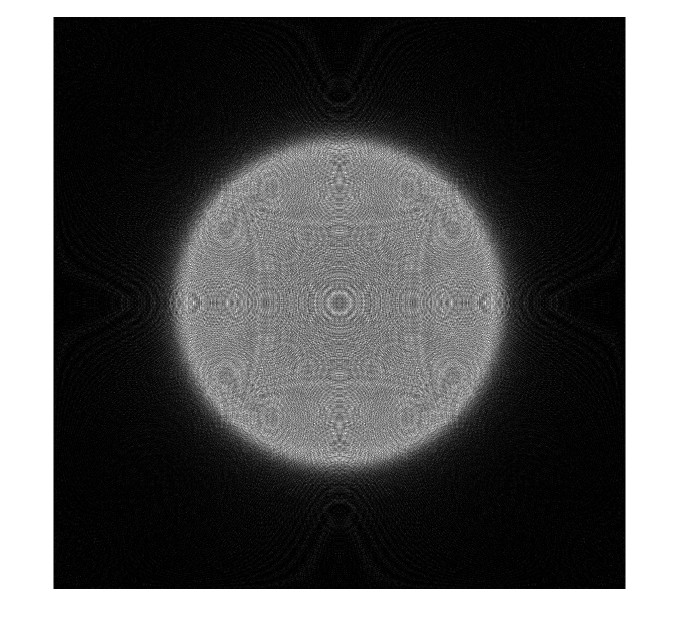

r2_1=inf;
r2_2=16.745;
t2=3;
m2={'H-K9L'};
d2=6.4;
D2=12;

lens2=Lens([r2_1,r2_2],t2,d2,m2,lambda);
lens2.conic=-0.393;
lens2.polyCoe=zeros(1,9);
lens2.polyCoe(9)=2.457472943507965E-006;
lens2.polyCoe(7)=-2.032144967384320E-005;
lens2.polyCoe(5)=3.648590237081279E-004;
lens2.polyCoe=flip(lens2.polyCoe);


area1=D1;
Lens.lensThickFcnGnr(lens1,D1,N);
Lens.lensThickFcnGnr(lens2,D1,N);
beams=GaussianBeam.waistProfile(beam,N,rate);
F=transform(beams,area1,lambda,10,[rate,rate]);
afterLens=ASMinLens(F,lens1,lambda,area1);
F=transform(afterLens,area1,lambda,14.5,[rate,rate]);
afterLens=ASMinLens(F,lens2,lambda,area1);
F=transform(afterLens,area1,lambda,30,[rate,rate]);
imshow(abs(F).^2,[])

lens1.thick_edge=lens1.thick_edge(N/2,:,:);
lens1.thick_air=lens1.thick_air(N/2,:,:);
lens2.thick_edge=lens2.thick_edge(N/2,:,:);
lens2.thick_air=lens2.thick_air(N/2,:,:);
beams=beams(N/2,:);

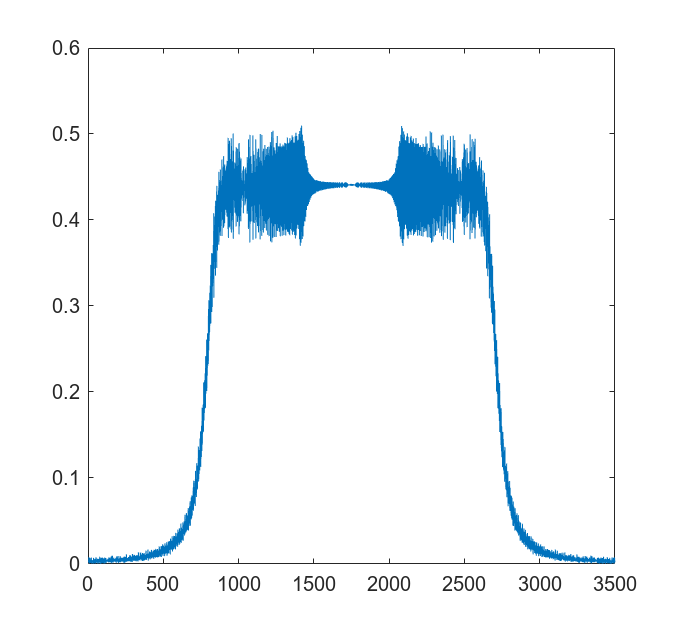

distance1=linspace(0,15,N)';
afterLens=ASMinLens(beams,lens1,lambda,[rate,area1]);
F=transform(afterLens,[rate,area1],lambda,distance1,[rate,rate]);
%imshow(abs(F').^2,[])
plot(abs(F(3500,:)).^2)